# Figure 1C

**Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A026_data.mat'],'S','settings','allIF');

conditions = settings.conditions

conditions = 24×6 cell array
    {'DMSO Longterm'         }    {[1 2 3]}    {[2]}    {[                1]}    {[0 0 0]}    {[0 10]}
    {'DMSO 6hr spike'        }    {[4 5 6]}    {[2]}    {[1 2 3 4 5 6 7 8 9]}    {[0 0 0]}    {[0 10]}
    {'DMSO 1hr spike'        }    {[  7 8]}    {[2]}    {[1 2 3 4 5 6 7 8 9]}    {[0 0 0]}    {[0 10]}
    {'DMSO CDK1i Longterm'   }    {[1 2 3]}    {[3]}    {[1 2 3 4 5 6 7 8 9]}    {[0 0 0]}    {[0 10]}
    {'DMSO CDK1i 6hr spike'  }    {[4 5 6]}    {[3]}    {[1 2 3 4 5 6 7 8 9]}    {[0 0 0]}    {[0 10]}
    {'DMSO CDK1i 1hr spike'  }    {[  7 8]}    {[3]}    {[1 2 3 4 5 6 7 8 9]}    {[0 0 0]}    {[0 10]}
    {'DMSO CDK2i Longterm'   }    {[1 2 3]}    {[4]}    {[1 2 3 4 5 6 7 8 9]}    {[0 0 0]}    {[0 10]}
    {'DMSO CDK2i 6hr spike'  }    {[4 5 6]}    {[4]}    {[1 2 3 4 5 6 7 8 9]}    {[0 0 0]}    {[0 10]}
    {'DMSO CDK2i 1hr spike'  }    {[  7 8]}    {[4]}    {[1 2 3 4 5 6 7 8 9]}    {[0 0 0]}    {[0 10]}
    {'DMSO CDK1/2i Longterm' }    {[1 2 3]} 


 framesPerHr = 60/12;
 frameEdU = 0;
 timeStart = 0;
 folding =5;
 numFrames = size(S(1).area,2);
 xFrames = 1:numFrames;
 xTime = (xFrames-1)./framesPerHr;

 times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
 [S.POI_time] = times{:};

  for i = 1:length(S)
    
     S(i).POI_realtime = S(i).POI/framesPerHr;
  end

1 Cell trace (number 898 randomly selected)

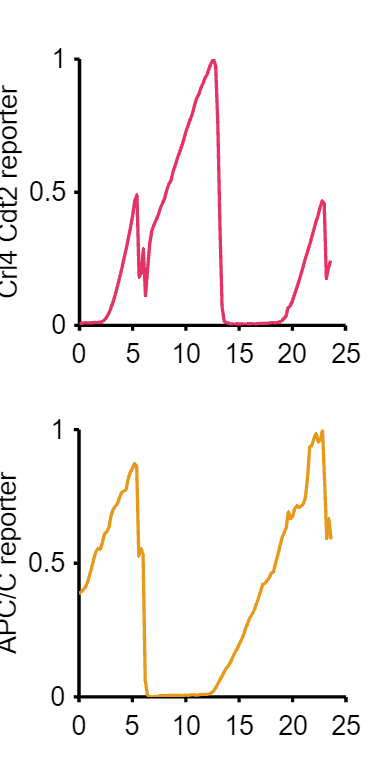

%G1
figure ('units','inches','position',[0 0 4 8])

conds = [1];
for i=1:length(conds)

    inds = true(size(S(conds(i)).apcNormM(:,1))) & S(conds(i)).POI_realtime(:,6)>20  & S(conds(i)).POI_realtime(:,1)>2 ;

    % cells = find(inds); %all possible cells
    nums =898; % randomly selected

   
     subplot(2,1,1), plot(xTime,(S(conds(i)).crlNormAct(nums,:))','Color',[.9 .2 .4])
    
   
    ylabel('Crl4 Cdt2 reporter')
    ylim([0 1])
       xlim([0 25])
       xticks(0:5:25)
        xtickangle(0)
       axis square
         set(gca,'box','off')



    subplot(2,1,2), plot(xTime,S(conds(i)).apcNorm(nums,:)','Color',[.9 .6 .1])
   
    ylabel('APC/C reporter')
    ylim([0 1])
    xlim([0 25])
      xticks(0:5:25)
      xtickangle(0)
    axis square
    
       set(gca,'box','off')
   
end

% print_pdf('fig_1C.pdf')
